Neuroseries toolbox (former TStoolbox, for “Time Stamp”) is a class library for dealing with neurophysiological data in matlab (a python version also exists). Neuroseries is object-oriented, meaning that it is organized around objects instead of functions. An object is simply a struct where its associated functions are inside the struct instead of outside. This makes it easier to keep track of which functions work with which data types, as well as preventing confusion between different functions with the same name. Object-oriented programming (OOP) is the dominant paradigm in industry because it encourages code reusability by making code modular. More importantly, it forces you to do things in a certain way that simplifies things, makes code easier to read, and prevents you from making common mistakes.

In OOP, you start with “classes” and create “objects” from a particular class. Using Neuroseries requires you to understand a four different classes:

## 1) intervalSets. An intervalSet is an object containing a set of intervals, i.e. vectors of start and end times for each time interval. 

- This is used to store states of the animal or events that have a beginning and end. In OOP, to create an object from scratch you need to call a function called a “constructor”. In this case, the constructor is called IntervalSet(). For example:

% a simple example indicating when the animal is in the left side of the
% box

% fake data
left_zone_entry_times  = [11000 11600 12200]'; % animal enters left half of box
left_zone_exit_times   = [11200 11900 12600]'; % animal enters left half of box

% make intervalSet to hold this data
in_left      = intervalSet(left_zone_entry_times, left_zone_exit_times);
in_left.name = 'animal in left side of box';

% or alternatively, use buzcode format with t x 2 matrix
in_left      = intervalSet([left_zone_entry_times left_zone_exit_times]);
in_left.name = 'animal in left side of box';

in_left

in_left =   intervalSet with properties:

    version: 2
      start: [11000 11600 12200]
       stop: [11200 11900 12600]
       name: 'animal in left side of box'


You can reference any field in the object as if it were a struct

in_left.version

ans = 2

To access the methods for this object (i.e. the functions contained inside), type in_left. <tab> and it will bring up an autocomplete list. Here are some examples:

load RipplesSleep.mat % a struct we use to keep track of ripples
% The RipplesSleep struct has a field .epoch, which contains 
% an intervalSet for times when ripples are occurring.
RipplesSleep.epoch.name = 'ripples'; % this should have been in the mat file
RipplesSleep.epoch

ans =   intervalSet with properties:

    version: 2
      start: [1×4192 double]
       stop: [1×4192 double]
       name: 'ripples'



% merging ripples closer than 0.1 seconds together
merged_ripples = RipplesSleep.epoch.mergeCloseIntervals(0.1)

merged_ripples =   intervalSet with properties:

    version: 2
      start: [1×3886 double]
       stop: [1×3886 double]
       name: []




% dropping ripples shorter than 50 ms in duration
long_ripples_only = RipplesSleep.epoch.dropShortIntervals(0.05)

long_ripples_only =   intervalSet with properties:

    version: 2
      start: [1×313 double]
       stop: [1×313 double]
       name: []


You can combine two intervalSets in several different ways. For example, if you wanted only to look at ripples that occured when the animal was in the left side of the box, make a new intervalSet

ripples_on_left = in_left & RipplesSleep.epoch

ripples_on_left =   intervalSet with properties:

    version: 2
      start: [1×23 double]
       stop: [1×23 double]
       name: []


% you can do union, intersection, etc. The & and | operators
% work, or you can use
% first_intervalSet.intersection(second_intervalSet)


Or if you wanted to look only at ripples that occurred when the animal was NOT in the left side

ripples_not_on_left = RipplesSleep.epoch - in_left

ripples_not_on_left =   intervalSet with properties:

    version: 2
      start: [1×4169 double]
       stop: [1×4169 double]
       name: []


## 2) TS - a TS is an object that holds TimeStamps:

- The TS object stores a list of time stamps, i.e. a list of times when an event occurred. This is most often the spike times for an individual unit, but it could also be behavioral events, optogenetic stimuli, etc.

- A TS also holds an intervalSet over which the TS is defined. By default, when you make a new TS, the intervalSet is the interval from the first event to the last event.

- Confusingly, in the documentation, "tsa" is used as the name of an example ts, e.g. tsa = ts(time_stamps);

% a TS holding one unit recorded from the NAc
load one_unit.mat
one_unit

one_unit =   55561×1 ts array with properties:

              version: 1
                    t: [55561×1 double]
               t_info: 'spike times'
                 data: []
            data_info: []
         timeInterval: [1×1 intervalSet]
    timeInterval_info: 'intervalSet over which spike times are defined'
                 name: 'spike train'


If you want to extract the vector of spike times, you can use one_unit.t 

Note that the data field is empty - we will explain this below.

You can look at the intervalSet contained within one_unit, and it is just the interval from the first spike to the last spike:

one_unit.timeInterval

ans =   intervalSet with properties:

    version: 2
      start: 0.0945
       stop: 2.3330e+04
       name: []


Now we can do something useful. What if we wanted to extract just the spikes that occur during ripples?

ripple_spikes = one_unit.Restrict(RipplesSleep.epoch)

ripple_spikes =   340×1 ts array with properties:

              version: 2
                    t: [340×1 double]
               t_info: 'spike times'
                 data: []
            data_info: []
         timeInterval: [1×1 intervalSet]
    timeInterval_info: 'intervalSet over which spike times are defined'
                 name: 'spike train'


ripple_spikes.timeInterval

ans =   intervalSet with properties:

    version: 2
      start: [1×4192 double]
       stop: [1×4192 double]
       name: []


Note that the new intervalSet contained within ripple_spikes.timeInterval is not the same as RipplesSleep.epoch: it is the **intersection** of RipplesSleep.epoch with one_unit.timeInterval

We can use this to look at the firing rate of that unit during ripples

ripple_spikes.rate()

ans = 2.2521

or the firing rate outside of ripples

no_ripples = one_unit.timeInterval - RipplesSleep.epoch % intervalSet when no ripples occur

no_ripples =   intervalSet with properties:

    version: 2
      start: [1×4193 double]
       stop: [1×4193 double]
       name: []



non_ripple_spikes = one_unit.Restrict(no_ripples)

non_ripple_spikes =   55221×1 ts array with properties:

              version: 2
                    t: [55221×1 double]
               t_info: 'spike times'
                 data: []
            data_info: []
         timeInterval: [1×1 intervalSet]
    timeInterval_info: 'intervalSet over which spike times are defined'
                 name: 'spike train'



non_ripple_spikes.rate()

ans = 2.3824

## 3) TSD - a TSD is an object that holds TimeStamps plus Data:

- Like a TS, a TSD contains **TimeStamps** and an **intervalSet**

- It also contains **Data**, meaning a number associated with each **TimeStamp**. The TS object is derived from the TSD object, which is why the TS object has a data field that is empty.

- Examples of TSDs would be the animal's X position as a function of time, in which each timestamp is associated with a measurement of the X position

- In the documentation, "tsa" is also used as the name of an example TSD, e.g. tsa = tsd(time_stamps, data_points);

% the animal's position
load pos.mat
pos

pos = struct with fields:
            X: [911336×1 tsd]
            Y: [911336×1 tsd]
    goodLedEp: [1×1 intervalSet]
      wstruct: [1×1 struct]
       linSpd: [911336×1 tsd]
       moveEp: [1×1 intervalSet]


% the pos struct contains three TSD's, for X position, Y position, and
% linear speed

pos.Y

ans =   911336×1 tsd array with properties:

              version: 1
                    t: [911336×1 double]
               t_info: 'time points'
                 data: [911336×1 double]
            data_info: 'values at time points'
         timeInterval: [1×1 intervalSet]
    timeInterval_info: 'intervalSet over which data is defined'
                 name: ''


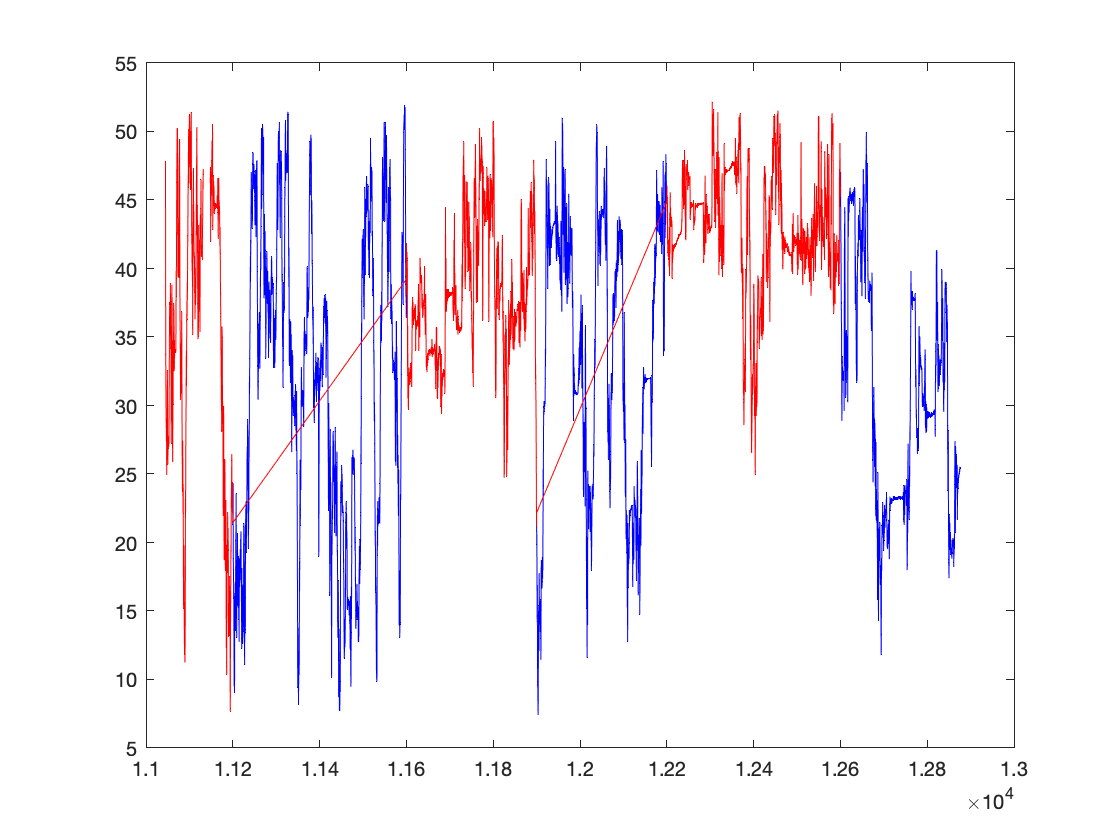


% we can plot pos.Y using the plot method
close all
p1 = pos.Y.plot();
p1.Color = [0 0 1];
hold on

% restricting the data to only times when the animal is in the 
% left side of the box
newY = pos.Y.Restrict(in_left);
p2 = newY.plot();
p2.Color = [1 0 0];

Some TStoolbox methods will generate TSD's. For example:

length_of_ripples = RipplesSleep.epoch.length()

length_of_ripples =   4192×1 tsd array with properties:

              version: 2
                    t: [4192×1 double]
               t_info: 'time points'
                 data: [4192×1 double]
            data_info: 'values at time points'
         timeInterval: [1×1 intervalSet]
    timeInterval_info: 'intervalSet over which data is defined'
                 name: ''


RipplesSleep.epoch is an intervalSet, but the length method returns a TSD containing the duration of each ripple event

## 4) tsdArray - an object that holds an array of TS's or TSD's

- This is not a MATLAB array of TS's, it's a specialized object for holding array data

- This is what you would use for a group of simultaneously recorded spike trains

- You could also use this to store numerical data in matrix format, e.g. binned spike trains or principal components. A key advantage of this is that each row of the matrix has a timestamp associated with it, and the object also contains the corresponding intervalSet

% now we'll load in some data recorded from the NAc
load NAcSpikes.mat

% NAcSpikes.S is a tsdArray holding 35 spike trains
NAcSpikes

NAcSpikes = struct with fields:
         S: [35×1 tsdArray]
     shank: [35×1 double]
    cellIx: [35×1 double]



NAcSpikes.S % for some reason this doesn't show up in the
% live script - you need to type it in the command window


NAcSpikes.S contains a cell array of TS's, each of which holds the spike train for one unit

% looking at NAcSpikes.S
C = NAcSpikes.S.C

C = 35×1 cell array
    {55561×1 ts}
    {19928×1 ts}
    {19020×1 ts}
    { 5915×1 ts}
    {24021×1 ts}
    { 7795×1 ts}
    {24336×1 ts}
    {24535×1 ts}
    {11720×1 ts}
    { 8584×1 ts}
    {40690×1 ts}
    {40339×1 ts}
    {43042×1 ts}
    {62165×1 ts}
    {54027×1 ts}
    {18084×1 ts}


C{1}

ans =   55561×1 ts array with properties:

              version: 1
                    t: [55561×1 double]
               t_info: 'spike times'
                 data: []
            data_info: []
         timeInterval: [1×1 intervalSet]
    timeInterval_info: 'intervalSet over which spike times are defined'
                 name: 'spike train'



% let's pretend to extract just the spikes from D1+ MSNs
isMSN = rand(35,1) < 0.7 % boolean vectors, 1 if MSN 

isMSN = 35×1 logical array
   1
   1
   1
   1
   0
   1
   1
   0
   1
   0


isD1  = rand(35,1) < 0.5 % boolean vectors, 1 if D1

isD1 = 35×1 logical array
   1
   0
   1
   0
   0
   1
   0
   1
   0
   0



% here are the spikes from D1+ MSNs
D1MSN_spikes = NAcSpikes.S(isMSN & isD1)

% here are their firing rates
D1MSN_spikes.Rate() % bug: Rate() works but rate() doesn't

ans =     2.3816
    0.8153
    0.3343
    1.8451
    2.6646
    0.2856
    0.5384
    0.3769
    3.2558
    1.2573



% let's look at the firing rate of those cells during ripples
D1MSN_ripple = D1MSN_spikes.Restrict(RipplesSleep.epoch)
D1MSN_ripple.Rate()

ans =     2.2521
    1.2386
    0.4840
    2.1196
    2.3846
    0.5103
    0.5565
    0.3776
    2.3448
    1.3051



% let's convert this to buzcode format
buzcode_cell_array_of_spikes = D1MSN_ripple.bzFormat()

buzcode_cell_array_of_spikes = 14×1 cell array
    {340×1 double}
    {187×1 double}
    { 73×1 double}
    {320×1 double}
    {360×1 double}
    { 77×1 double}
    { 84×1 double}
    { 57×1 double}
    {354×1 double}
    {197×1 double}
    {869×1 double}
    { 69×1 double}
    {708×1 double}
    {618×1 double}


There are a couple of relevant bugs with tsdArrays that were introduced between version 1 and version 2 that haven't been fully resolved

- in NAcSpikes.S, each TS has its own intervalSet, but it would be better if we made it so the entire tsdArray has only one intervalSet that's common to all of the elements

- Not all indexing is fully implemented in subsref(). For example, you can't get the first spike train by typing NAcSpikes.S.C{1}, but you can do it the way shown above

Now let's use a tsdArray that's a matrix of numbers. 

% this is the method for binning spike trains.
% we plan to rename it
binned_NAc_spikes = NAcSpikes.S.MakeQfromS(0.1)

binned_NAc_spikes =   233302×35 tsd array with properties:

              version: 2
                    t: [233302×1 double]
               t_info: 'time points'
                 data: [233302×35 double]
            data_info: 'values at time points'
         timeInterval: [1×1 intervalSet]
    timeInterval_info: 'intervalSet over which data is defined'
                 name: ''



% we can get just the bins that are during ripples
binned_ripple_spikes = binned_NAc_spikes.Restrict(RipplesSleep.epoch)

binned_ripple_spikes =   1466×35 tsd array with properties:

              version: 2
                    t: [1466×1 double]
               t_info: 'time points'
                 data: [1466×35 double]
            data_info: 'values at time points'
         timeInterval: [1×1 intervalSet]
    timeInterval_info: 'intervalSet over which data is defined'
                 name: ''


## The idea with Neuroseries is to update the old TStoolbox and make it fully interchangeable with the new Python version. 